
n = 100

n = 100

A1 = zeros(n);
A2 = zeros(n);
A3 = zeros(n);
A4 = zeros(n);

for i = 1 : n
    for j = 1 : n
        A1(i,j) = 255*i/n;
    end
end
for i = 1 : n
    for j = 1 : n
        A2(j,i) = 255*i/n;
    end
end
for i = 1 : n
    for j = 1 : n
        A3(j,i) = 255*(i+j)/n/2;
    end
end
for i = 1 : n
    for j = 1 : n
        A4(n-j+1,i) = 255*(i+j)/n/2;
    end
end

f1 = figure('Position', [50, 50, 1050, 850]);

ax1 = subplot(2,2,1);
image(A1);
colormap(ax1, 'parula');
colorbar;
grid on
title('colormap = parula')
ylabel("Высота, px")
xlabel("Ширина, px")




ax2 = subplot(2,2,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


image(A2);
colormap(ax2, 'cool');
colorbar;
grid on
title('colormap = cool')
ylabel("Высота, px")
xlabel("Ширина, px")



ax3 = subplot(2,2,3)

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


im3 = image(A3);
colormap(ax3, 'gray');
colorbar;
grid on
title('colormap = gray')
ylabel("Высота, px")
xlabel("Ширина, px")



ax4 = subplot(2,2,4)

ax4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


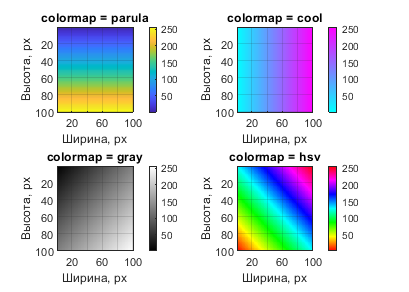

im4 = image(A4);
colormap(ax4, 'hsv');
colorbar;
grid on
title('colormap = hsv')
ylabel("Высота, px")
xlabel("Ширина, px")

saveas(f1, 'LABPIC.png')